% =======================================================================
% cnn_main.mlx
%
% Live Script principale per:
%  - Caricamento dataset ORL
%  - Split train/test
%  - Data augmentation
%  - Training (cnn_train_full)
%  - Test (cnn_test_full)
%  - Plot delle statistiche
%  
% Gli override e le funzioni di utilità sono in file separati:
%    • augment_data.m
%    • cnn_train_full.m
%    • cnn_test_full.m
%    • maxpool2d_backward.m
% =======================================================================
clear; clc; close all;
rng(0);

%% 1) PARAMETRI GLOBALI
epochs       = 40;        % numero di epoche
base_lr      = 0.01;      % learning rate iniziale
lambda       = 1e-4;      % L2 weight decay
dropout_rate = 0.2;       % dropout (20% spenti)
batch_size   = 32;        % dimensione dei mini‐batch
patience     = 5;         % early stopping su validation

%% 2) CARICAMENTO DATASET ORL
load('dataset/volti_dataset.mat');  % A (m×n), labels
img_h       = 112; 
img_w       = 92; 
num_classes = max(labels);          % 40 classi
A           = double(A) / 255;      % normalizzazione 0‐1
imgs        = reshape(A, img_h, img_w, []);  % [112×92×400]
labels      = labels(:);                     % [400×1]

%% 3) SPLIT TRAIN/TEST 5 VS 5
train_idx = [];  
test_idx  = [];
for s = 1:num_classes
    idx_s = find(labels == s);
    idx_s = idx_s(randperm(length(idx_s)));
    train_idx = [train_idx; idx_s(1:5)];   % 5 immagini per persona → train
    test_idx  = [test_idx;  idx_s(6:end)]; % 5 immagini per persona → test
end
imgs_train_base = imgs(:, :, train_idx);  % [112×92×200]
y_train_base    = labels(train_idx)';     % [1×200]
imgs_test       = imgs(:, :, test_idx);   % [112×92×200]
y_test          = labels(test_idx)';      % [1×200]

%% 4) DATA AUGMENTATION SU TRAIN BASE (×12)
[imgs_train_aug, y_train_aug] = augment_data(imgs_train_base, y_train_base);

%% 5) CREAZIONE DEL VALIDATION SET (20% DI TRAIN AUMENTATO)
N_aug     = size(imgs_train_aug, 3);
perm_aug  = randperm(N_aug);
val_count = round(0.20 * N_aug);
val_idx   = perm_aug(1:val_count);
train_idx = perm_aug(val_count+1:end);

imgs_train_eff = imgs_train_aug(:, :, train_idx);   % [112×92×1920]
y_train_eff    = y_train_aug(:, train_idx);          % [1×1920]
imgs_val       = imgs_train_aug(:, :, val_idx);     % [112×92×480]
y_val          = y_train_aug(:, val_idx);            % [1×480]

% One-hot per train e validation
Y_train_eff = zeros(num_classes, numel(y_train_eff));
for j = 1:numel(y_train_eff)
    Y_train_eff(y_train_eff(j), j) = 1;
end
Y_val = zeros(num_classes, numel(y_val));
for j = 1:numel(y_val)
    Y_val(y_val(j), j) = 1;
end

%% 6) DEFINIZIONE ARCHITETTURA DELLA CNN
% (3 conv + pool, poi fully‐connected)
f1   = 3;  n_f1 = 8;
f2   = 3;  n_f2 = 16;
f3   = 3;  n_f3 = 8;
pool = 2;

% Calcolo dimensioni feature map
conv1_h = img_h - f1 + 1;   conv1_w = img_w - f1 + 1;
pool1_h = floor(conv1_h / pool);  pool1_w = floor(conv1_w / pool);

conv2_h = pool1_h - f2 + 1; conv2_w = pool1_w - f2 + 1;
pool2_h = floor(conv2_h / pool); pool2_w = floor(conv2_w / pool);

conv3_h = pool2_h - f3 + 1; conv3_w = pool2_w - f3 + 1;
pool3_h = floor(conv3_h / pool); pool3_w = floor(conv3_w / pool);

fc_input_size = pool3_h * pool3_w * n_f3;  % 12×9×8 = 864
fprintf('[DEBUG arch] fc_input_size (layer 3) = %d\n', fc_input_size);

[DEBUG arch] fc_input_size (layer 3) = 864



% Inizializzo pesi He‐init per conv + FC
rng(0);
filters1 = randn(f1, f1, n_f1) * sqrt(2/(f1*f1*n_f1));   bias1 = zeros(n_f1, 1);
filters2 = randn(f2, f2, n_f2, n_f1) * sqrt(2/(f2*f2*n_f2)); bias2 = zeros(n_f2, 1);
filters3 = randn(f3, f3, n_f3, n_f2) * sqrt(2/(f3*f3*n_f3)); bias3 = zeros(n_f3, 1);

W_fc = randn(num_classes, fc_input_size) * sqrt(2 / fc_input_size);
b_fc = zeros(num_classes, 1);

%% 7) TRAINING CON MINI‐BATCH, LR SCHEDULING, DROPOUT, L2, EARLY STOPPING
[params, loss_hist, acc_hist, val_loss_hist, val_acc_hist] = ...
    cnn_train_full( ...
        imgs_train_eff, Y_train_eff, imgs_val, Y_val, ...
        f1, n_f1, f2, n_f2, f3, n_f3, pool, ...
        epochs, base_lr, lambda, dropout_rate, batch_size, patience ...
    );

[EPOCA  1] Train Loss=3.6865 Acc=2.29% | Val Loss=3.7009 Acc=2.85%
[EPOCA  2] Train Loss=3.6575 Acc=4.32% | Val Loss=3.6761 Acc=5.08%
[EPOCA  3] Train Loss=3.6327 Acc=5.54% | Val Loss=3.6434 Acc=8.74%
[EPOCA  4] Train Loss=3.5800 Acc=7.37% | Val Loss=3.5648 Acc=12.60%
[EPOCA  5] Train Loss=3.4587 Acc=10.32% | Val Loss=3.3346 Acc=16.06%
[EPOCA  6] Train Loss=3.1561 Acc=14.28% | Val Loss=2.7541 Acc=39.02%
[EPOCA  7] Train Loss=2.6133 Acc=26.58% | Val Loss=1.8932 Acc=57.11%
[EPOCA  8] Train Loss=1.9625 Acc=44.00% | Val Loss=1.1494 Acc=77.44%
[EPOCA  9] Train Loss=1.3081 Acc=63.26% | Val Loss=0.7081 Acc=79.88%
[EPOCA 10] Train Loss=0.8829 Acc=74.39% | Val Loss=0.4429 Acc=89.63%
[EPOCA 11] Train Loss=0.6067 Acc=82.57% | Val Loss=0.2835 Acc=93.29%
[EPOCA 12] Train Loss=0.4244 Acc=87.45% | Val Loss=0.1834 Acc=96.75%
[EPOCA 13] Train Loss=0.3371 Acc=89.33% | Val Loss=0.1425 Acc=97.15%
[EPOCA 14] Train Loss=0.2602 Acc=92.02% | Val Loss=0.1002 Acc=98.37%
[EPOCA 15] Train Loss=0.2095 Acc=93.34% |


%% 8) VALUTAZIONE SUL TEST SET
fprintf('\n>>> Valutazione modello su TEST SET...\n');


>>> Valutazione modello su TEST SET...


acc_test = cnn_test_full(imgs_test, y_test, params);
fprintf('Accuracy finale sul TEST SET: %.2f%%\n', acc_test);

Accuracy finale sul TEST SET: 91.71%


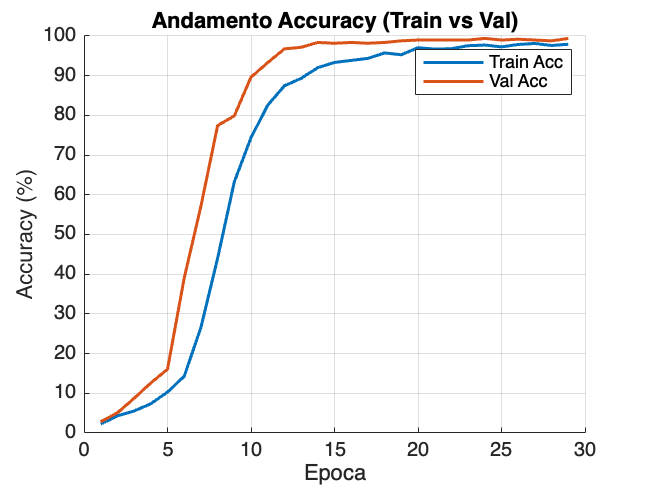


%% 9) PLOTTAGGIO STATISTICHE
figure; hold on;
plot(1:length(loss_hist), loss_hist, 'LineWidth', 1.5);
plot(1:length(val_loss_hist), val_loss_hist, 'LineWidth', 1.5);
xlabel('Epoca'); ylabel('Loss');
legend('Train Loss', 'Val Loss');
title('Andamento Loss (Train vs Val)'); grid on;

figure; hold on;
plot(1:length(acc_hist), acc_hist, 'LineWidth', 1.5);
plot(1:length(val_acc_hist), val_acc_hist, 'LineWidth', 1.5);
xlabel('Epoca'); ylabel('Accuracy (%)');
legend('Train Acc', 'Val Acc');
title('Andamento Accuracy (Train vs Val)'); grid on;